fileLocation = uigetdir("C:\Users\xxoox\Downloads\MATLAB works\Data\Concrete");

dsConcrete = imageDatastore(fileLocation,"IncludeSubFolders",true,"LabelSource","foldernames");
categories(dsConcrete.Labels)

ans = 2×1 cell array
    {'Negative'}
    {'Positive'}



dsConcrete.Labels = renamecats(dsConcrete.Labels,["No Crack" "Crack"]);
categories(dsConcrete.Labels)

ans = 2×1 cell array
    {'No Crack'}
    {'Crack'   }



[dsTrain,dsTest] = splitEachLabel(dsConcrete,0.8,"randomize");
countEachLabel(dsTrain)

ans = 2×2 table
     Label      Count
    ________    _____

    No Crack     400 
    Crack        400 


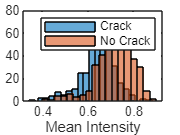


concreteTable = extractConcreteFeatures(dsTrain);

save ("concreteIntensityFeatures.mat concreteTable dsTrain dsTest");

histogram(concreteTable.intensityAvg(concreteTable.label == "Crack"),20)
hold on
histogram(concreteTable.intensityAvg(concreteTable.label == "No Crack"),20)
hold off
xlabel("Mean Intensity")
legend("Crack","No Crack")

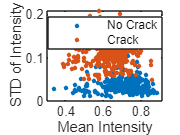


gscatter(concreteTable.intensityAvg,concreteTable.intensitySTD,concreteTable.label)
xlabel("Mean Intensity")
ylabel("STD of Intensity")